                                                        % 2D Fourier spectrum
% Problem 1
cTP = imread('characterTestPattern.tif');
 cTP = im2double(cTP);
 imshow(cTP);
 
 F = fftshift(fft2(cTP));
 A = log(1 + abs(F));
 A = A/max(A(:));
 imshow(A);
 imwrite(A, 'Spec1.png')
 cTP_shift = circshift(cTP, [100, -200]);
 imshow(cTP_shift);
 

% Probelm 2
 
 F2 = fftshift(fft2(cTP_shift));
 A2 = log(1 + abs(F2));
 A2 = A2/max(A2(:));
 imshow(A2)
 imwrite(A2, 'Spec2.png')
 

 % Probelm 3
 
 cTP_rot = imrotate(cTP, 15, 'bicubic');
 imshow(cTP_rot)
 

  % Probelm 4
 
 F3 = fftshift(fft2(cTP_rot));
 A3 = log(1 + abs(F3));
 A3 = A3/max(A3(:));
 imshow(A3)
 imwrite(A3, 'Spec3.png')

 % Probelm 5
 
 cTP2 = imread('characterTestPattern_2.tif');
 cTP2 = im2double(cTP2);
 imshow(cTP2)
 

 % Problem 6
 
 F = fftshift(fft2(cTP2));
 A = log(1 + abs(F));
 A = A/max(A(:));
 imshow(A)
 imwrite(A, 'Spec4.png')

% Problem 8 (problem 7 teorietskt)

 cTP3 = imread('characterTestPattern_3.tif');
 cTP3 = im2double(cTP3);
 imshow(cTP3)
 

 % Problem 9
 
 F = fftshift(fft2(cTP3));
 A = log(1 + abs(F));
 A = A/max(A(:));
 imshow(A)
 imwrite(A, 'Spec5.png')
 
 % problem 10 teoretisk

                                                        % Period and Frequency
 
 v2 = imread('verticalbars_2.tif');
 imshow(v2)
 
 F = fftshift(fft2(v2));
 A = log(1 + abs(F));
 A = A/max(A(:));
 imshow(A)
 imwrite(A, 'Spec6.png')
 

 % Problem 11
 v4 = imread('verticalbars_4.tif');
 
 F = fftshift(fft2(v2));
 A = log(1 + abs(F));
 A = A/max(A(:));
 imshow(A)
 imwrite(A, 'Spec6.png')
 
 %(Probelm 12-13 teoretiska)

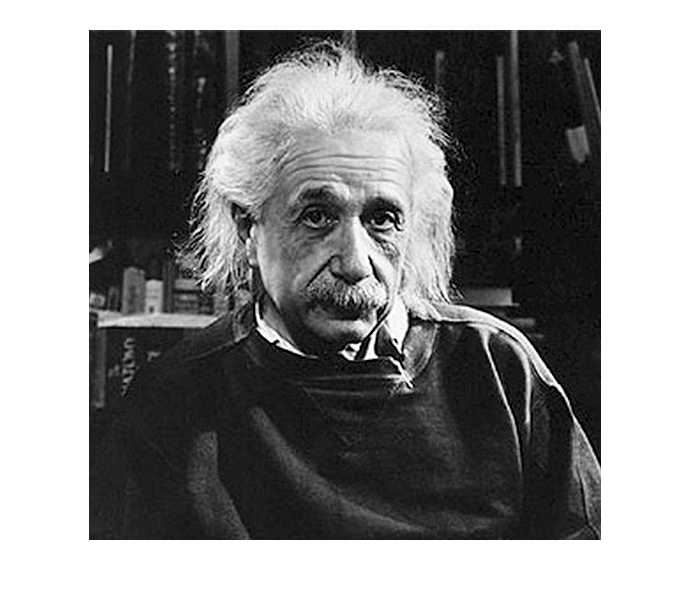


                                            % Importance of spectrum and phase angle
 
 E1 = imread('Einstein1.jpg');
 E1 = im2double(E1);
 imshow(E1)

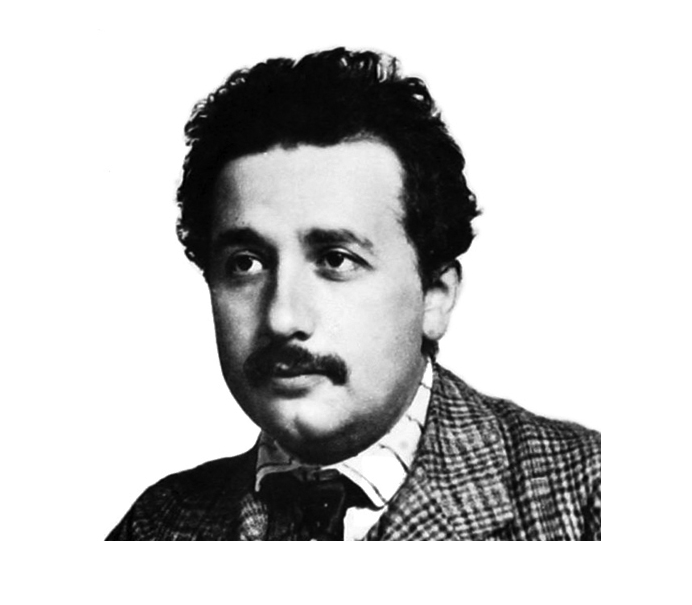

 
 E2 = imread('Einstein2.jpg');
 E2 = im2double(E2);
 imshow(E2)

 
 F1 = fftshift(fft2(E1));
 F2 = fftshift(fft2(E2));
 
 ang1 = angle(F1);
 ang2 = angle(F2);
 S1 = abs(F1);
 S2 = abs(F2);

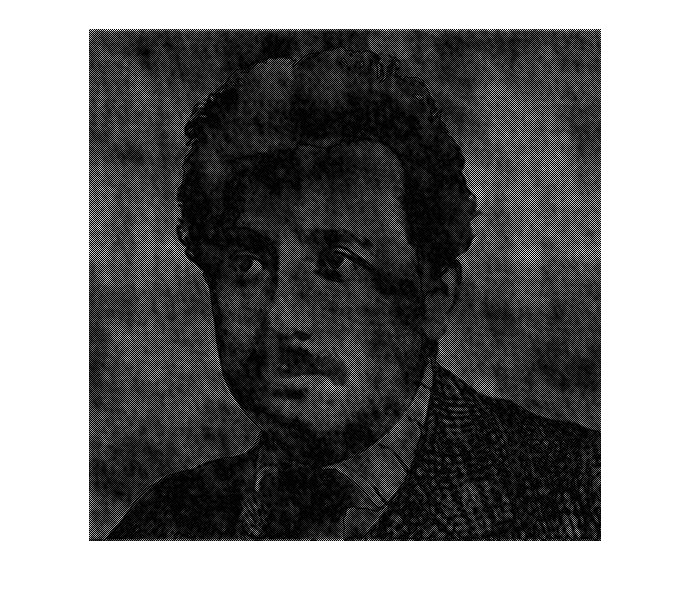

 % Problem 14
 
 Prob14 = real(ifft2(S1.*exp(i * ang2)));
 imshow(Prob14)

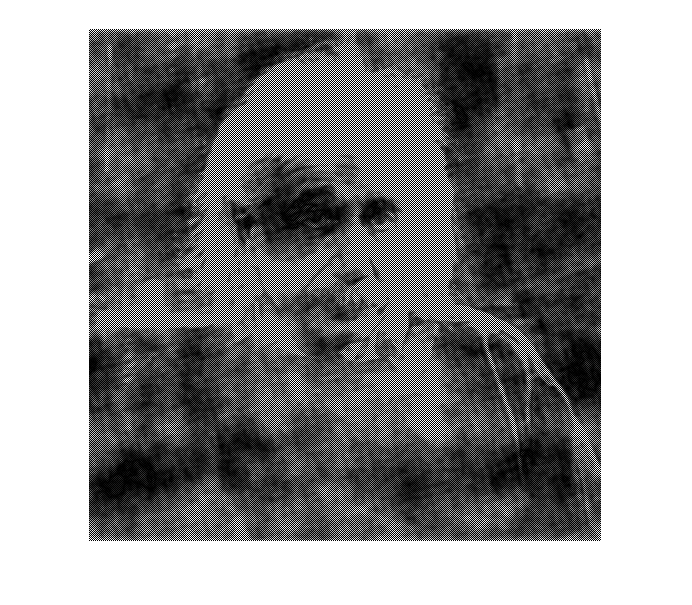

 imwrite(Prob14, 'E1_E2.png')
 
 % Problem 15
 Prob15 = real(ifft2(S2.*exp(i * ang1)));
 imshow(Prob15)

 imwrite(Prob15, 'E2_E1.png')
 
 

clear
f = imread('characterTestPattern.tif');
f = im2double(f);
imshow(f)
bild = FilterFreq(f, 1000);
imshow(bild)

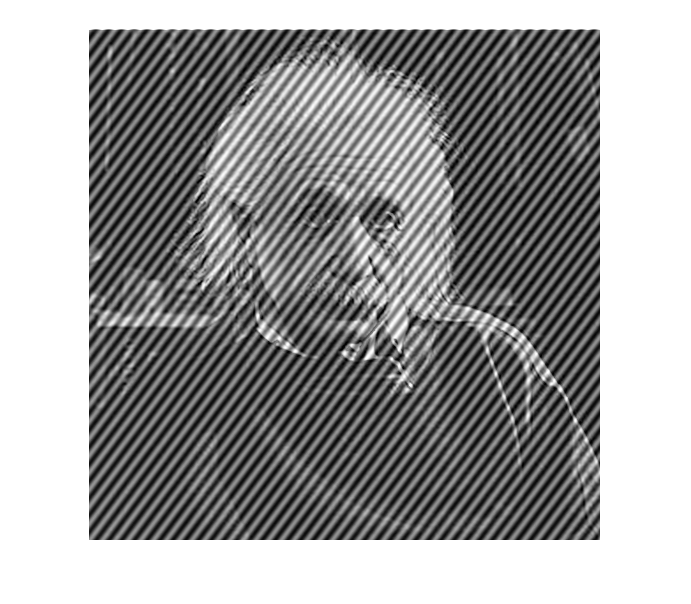

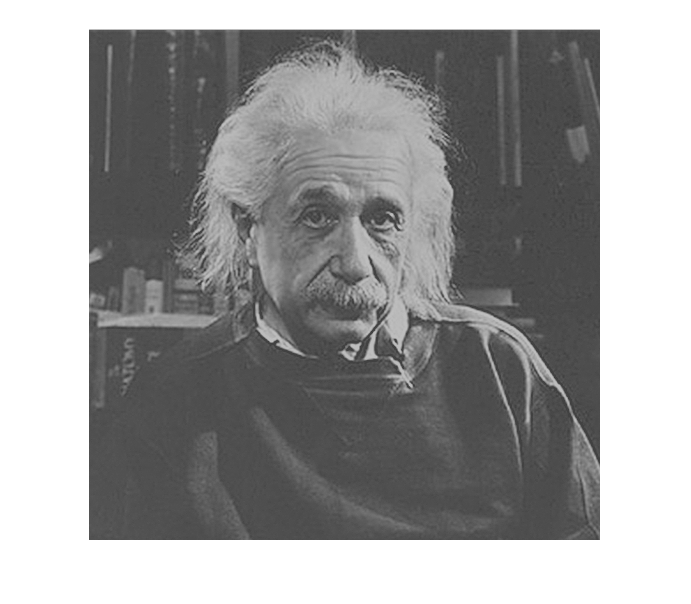

clear

%in = imread('astronaut-interference.tif');
%in = im2double(in);
%bild = RemoveSinusoidalNoise2(in,1);
%imshow(bild)

in2 = imread('Einstein_odd_sinus.tif');
in2 = im2double(in2);
bild2 = RemoveSinusoidalNoise2(in2,1);

imshow(bild2)


%in3 = imread('Einstein_sinus_1.tif');
%in3 = im2double(in3);
%bild3 = RemoveSinusoidalNoise2(in3,2);
%imshow(bild3)

%in4 = imread('Einstein_sinus_2.tif');
%in4 = im2double(in4);
%bild4 = RemoveSinusoidalNoise2(in4,2);
%bild4 = RemoveSinusoidalNoise2(bild4,2);
%imshow(bild4)

%in5 = imread('car-moire-pattern.tif');
%in5 = im2double(in5);
%bild5 = RemoveSinusoidalNoise2(in5,2);
%bild5 = RemoveSinusoidalNoise2(bild5,2);
%imshow(bild5)